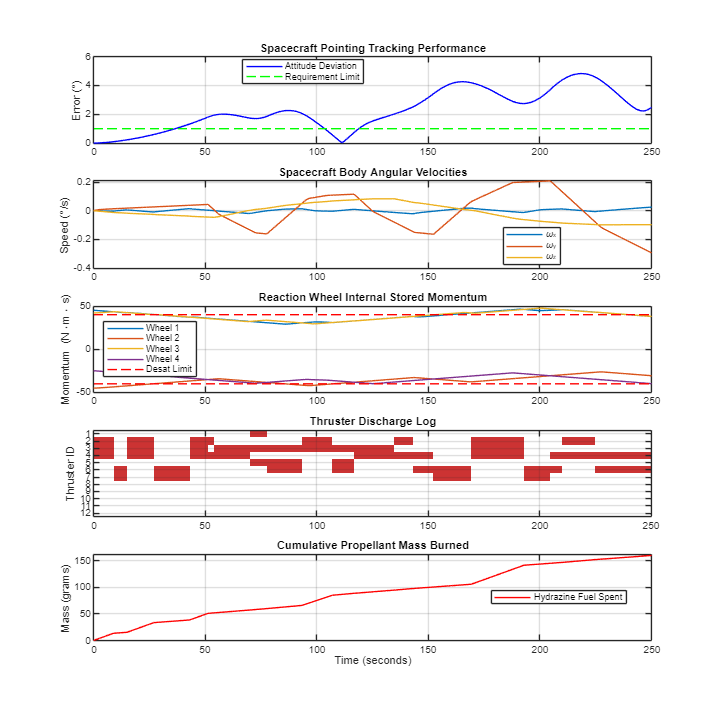

clear; clc; close all;

%% =========================
%% SIMULATION CONFIGURATION
%% =========================

% ======================================
% THESE CHANGE BASED ON FINAL STRUCTURE:
% ======================================
% Inertia Matrix
J = [ 17366.21,      0.00,      1.95;
          0.00,   3064.17,      0.44;
          1.95,      0.44,  14974.94 ];

% Center of Mass (CoM) Offset
CoM_offset = [0.00; 0.00; 0.95]; 

% Natural Frequency on Each Axis
wn = [0.5; 0.5; 0.163];
% ======================================

% Initial Attitude Misalignment Vector
initial_attitude_error_deg = [0.0, 0.0, 0.0];

% Initial Wheel Momentum Vector
initial_wheel_momentum = [45.0; -45.0; 42.0; -25.0]; 

% Constant External Space Disturbance Torques (N-m)
torque_disturbance = [0.03; -0.02; 0.015]; 

% Hardware Limits and Configuration
max_wheel_torque    = 0.20;
max_wheel_momentum  = 100.0;
desat_trigger_limit = 40.0;
F_thruster          = 4.5;
wheel_angle_deg     = 31.2;

% Heritage-Based Specifications
max_slew_rate_deg       = 0.1;
deadband_rad_deg        = 1.0;
pointing_target_rad_deg = 1.0;

% Simulation Time-Keeping
dt    = 0.1;
t_end = 250.0;

%% ========================
%% ACS COMPUTATION SECTION
%% ========================

% Process Inertia and Constraints
J_inv = inv(J);

max_slew_rate       = deg2rad(max_slew_rate_deg);
deadband_rad        = deg2rad(deadband_rad_deg);
pointing_target_rad = deg2rad(pointing_target_rad_deg);

Isp = 220.0;
g0  = 9.80665;

% Reaction Wheel Geometry Matrix
alpha = deg2rad(wheel_angle_deg);
W_wheels = [cos(alpha),      0, -cos(alpha),       0;
                0,  cos(alpha),       0, -cos(alpha);
           sin(alpha),  sin(alpha),  sin(alpha),  sin(alpha)];
W_wheels_pinv = pinv(W_wheels);

% RCS Thruster Placement Geometry Matrix
r1_structural = [1.2; 1.1; 1.2];
r2_structural = [-1.2; 1.1; -1.2];
r3_structural = [-1.2; -1.1; 1.2];
r4_structural = [1.2; -1.1; -1.2];

r1 = r1_structural - CoM_offset(:);
r2 = r2_structural - CoM_offset(:);
r3 = r3_structural - CoM_offset(:);
r4 = r4_structural - CoM_offset(:);

t1_X = [1;0;0];
t1_Y = [0;1;0];  
t1_Z = [0;0;1];

t2_X = [-1;0;0];
t2_Y = [0;1;0];  
t2_Z = [0;0;-1];

t3_X = [-1;0;0];
t3_Y = [0;-1;0]; 
t3_Z = [0;0;1];

t4_X = [1;0;0];
t4_Y = [0;-1;0]; 
t4_Z = [0;0;-1];

W_thrusters = [ ...
    cross(r1, F_thruster*t1_Z), cross(r1, F_thruster*t1_X), cross(r1, F_thruster*t1_Y), ...
    cross(r2, F_thruster*t2_Z), cross(r2, F_thruster*t2_X), cross(r2, F_thruster*t2_Y), ...
    cross(r3, F_thruster*t3_Z), cross(r3, F_thruster*t3_X), cross(r3, F_thruster*t3_Y), ...
    cross(r4, F_thruster*t4_Z), cross(r4, F_thruster*t4_X), cross(r4, F_thruster*t4_Y)  ...
];

W_thrusters_pinv = pinv(W_thrusters);

% Feedback Tuning
J_diag = diag(J);
Kp = J_diag .* (wn.^2);
Kd = 2 .* J_diag .* wn;
Ki = Kp .* 0.01;

time = 0:dt:t_end;    
num_steps = length(time);

% Process Initial State Conditions
r_xyz = deg2rad(initial_attitude_error_deg);
c_xyz = cos(r_xyz/2); s_xyz = sin(r_xyz/2);
q_current = [ c_xyz(1)*c_xyz(2)*c_xyz(3) + s_xyz(1)*s_xyz(2)*s_xyz(3); ...
              s_xyz(1)*c_xyz(2)*c_xyz(3) - c_xyz(1)*s_xyz(2)*s_xyz(3); ...
              c_xyz(1)*s_xyz(2)*c_xyz(3) + s_xyz(1)*c_xyz(2)*s_xyz(3); ...
              c_xyz(1)*c_xyz(2)*s_xyz(3) - s_xyz(1)*s_xyz(2)*c_xyz(3) ];

omega_current = [0.0; 0.0; 0.0];         
q_target      = [1.0; 0.0; 0.0; 0.0];
omega_target  = [0.0; 0.0; 0.0];

h_wheels            = initial_wheel_momentum(:);
desat_active        = false;            
fuel_burned         = 0.0;             
pulse_lockout_timer = 0;  
integral_epsilon    = [0.0; 0.0; 0.0];

% Data Storage
q_history              = zeros(4, num_steps);
error_angle_history    = zeros(1, num_steps);
omega_history          = zeros(3, num_steps);
wheel_torque_history   = zeros(4, num_steps);
wheel_momentum_history = zeros(4, num_steps);
thruster_fire_history  = zeros(12, num_steps);
fuel_history           = zeros(1, num_steps); 

% Simulation Loop
for step = 1:num_steps
    q_err = get_quaternion_error(q_current, q_target);
    epsilon = q_err(2:4);
    pointing_error_angle = 2 * acos(max(min(q_err(1), 1.0), -1.0));
    integral_epsilon = integral_epsilon + epsilon * dt;
    integral_epsilon = max(min(integral_epsilon, 1.0), -1.0);

    omega_commanded = (Kp ./ Kd) .* epsilon;
    if norm(omega_commanded) > max_slew_rate
        omega_commanded = (omega_commanded / norm(omega_commanded)) * max_slew_rate;
    end
    omega_desired = omega_target + omega_commanded;
    omega_error = omega_desired - omega_current;
    
    torque_cmd_attitude = (Kd .* omega_error) + (Ki .* integral_epsilon);

    if step > 1
        h_wheels = h_wheels - (wheel_torque_history(:, step-1) * dt);
    end
    h_wheels = max(min(h_wheels, max_wheel_momentum), -max_wheel_momentum);
    wheel_momentum_history(:, step) = h_wheels;

    if any(abs(h_wheels) > desat_trigger_limit) && (pulse_lockout_timer <= 0)
        desat_active = true;
        pulse_lockout_timer = 40; 
    end

    thruster_commands = zeros(12, 1);
    torque_actual_from_thrusters = zeros(3, 1);

    if desat_active
        h_body = W_wheels * h_wheels;
        torque_pulse_3axis = -sign(h_body) * 0.40;
        
        lb = zeros(12, 1);
        ub = ones(12, 1);
        x0 = zeros(12, 1); 
        options = optimoptions('lsqlin', 'Display', 'none', 'Algorithm', 'active-set');
        thruster_commands = lsqlin(W_thrusters, torque_pulse_3axis, [], [], [], [], lb, ub, x0, options);
        
        torque_actual_from_thrusters = W_thrusters * thruster_commands;
        
        if all(abs(h_wheels) < 10.0)
            desat_active = false;
        end
    end
    
    if pulse_lockout_timer > 0
        pulse_lockout_timer = pulse_lockout_timer - 1;
    end

    wheel_torques_demand = W_wheels_pinv * torque_cmd_attitude;
    wheel_torques_demand = max(min(wheel_torques_demand, max_wheel_torque), -max_wheel_torque);
    
    torque_actual = (W_wheels * wheel_torques_demand) + torque_actual_from_thrusters + torque_disturbance;

    num_active_thrusters = sum(abs(thruster_commands) > 0.01);
    total_force_inst = sum(abs(thruster_commands)) * F_thruster;
    mdot = total_force_inst / (Isp * g0);
    fuel_burned = fuel_burned + (mdot * dt);

    q_history(:, step) = q_current;
    error_angle_history(step) = rad2deg(pointing_error_angle);
    omega_history(:, step) = omega_current;
    wheel_torque_history(:, step) = wheel_torques_demand;
    thruster_fire_history(:, step) = abs(thruster_commands) > 0.01;
    fuel_history(step) = fuel_burned * 1000;

    [q_current, omega_current] = dynamics_step_stable(q_current, omega_current, torque_actual, J, J_inv, dt, h_wheels, W_wheels);
end

% Plot Telemetry Results
figure('Position', [100, 100, 800, 800]);

subplot(5,1,1);
plot(time, error_angle_history, 'b-');
hold on;
plot([0 t_end], [rad2deg(pointing_target_rad) rad2deg(pointing_target_rad)], 'g--');   
grid on;
title('Spacecraft Pointing Tracking Performance');
ylabel('Error (°)');
legend('Attitude Deviation', 'Requirement Limit', 'Location', 'best');

subplot(5,1,2);
plot(time, rad2deg(omega_history));
grid on; title('Spacecraft Body Angular Velocities');
ylabel('Speed (°/s)');
legend('\omega_x', '\omega_y', '\omega_z', 'Location', 'best');

subplot(5,1,3);
plot(time, wheel_momentum_history);
hold on;
plot([0 t_end], [desat_trigger_limit desat_trigger_limit], 'r--');
plot([0 t_end], [-desat_trigger_limit -desat_trigger_limit], 'r--');
grid on;
title('Reaction Wheel Internal Stored Momentum');
ylabel('Momentum (N\cdotm\cdot s)');
legend('Wheel 1', 'Wheel 2', 'Wheel 3', 'Wheel 4', 'Desat Limit', 'Location', 'best');

subplot(5,1,4);
imagesc(time, 1:12, thruster_fire_history); 
colormap(gca, [1,1,1; 0.8,0.2,0.2]);
clim([0 1]);
grid on;
title('Thruster Discharge Log');
ylabel('Thruster ID');
set(gca, 'YTick', 1:12);

subplot(5,1,5);
plot(time, fuel_history, 'r-');
grid on;
title('Cumulative Propellant Mass Burned');
xlabel('Time (seconds)');
ylabel('Mass (grams)');
ylim([-0.5, max(max(fuel_history)+2, 5)]); 
legend('Hydrazine Fuel Spent', 'Location', 'best');


% Verification Report
final_error = error_angle_history(num_steps);
fprintf('\n=== MISSION VERIFICATION ===\n');


=== MISSION VERIFICATION ===


fprintf('Calculated Proportional Gains (Kp): [%.2f, %.2f, %.2f]\n', Kp(1), Kp(2), Kp(3));

Calculated Proportional Gains (Kp): [4341.55, 766.04, 397.87]


fprintf('Calculated Derivative Gains (Kd): [%.2f, %.2f, %.2f]\n', Kd(1), Kd(2), Kd(3));

Calculated Derivative Gains (Kd): [17366.21, 3064.17, 4881.83]


fprintf('Calculated Integral Gains (Ki): [%.4f, %.4f, %.4f]\n', Ki(1), Ki(2), Ki(3));

Calculated Integral Gains (Ki): [43.4155, 7.6604, 3.9787]


fprintf('Final Pointing Error: %.4f°\n', final_error);

Final Pointing Error: 2.4916°


fprintf('Total Fuel Expended:  %.2f grams\n', fuel_history(num_steps));

Total Fuel Expended:  160.30 grams


if final_error <= rad2deg(pointing_target_rad)
    fprintf('STATUS: MISSION SUCCESS (Within Bounds)\n');
else
    fprintf('STATUS: MISSION FAIL (Out of Bounds)\n');
end

STATUS: MISSION FAIL (Out of Bounds)


fprintf('=====================================\n');


% Helper Functions
function q_out = quat_multiply(q1, q2)
    w1 = q1(1); x1 = q1(2); y1 = q1(3); z1 = q1(4);
    w2 = q2(1); x2 = q2(2); y2 = q2(3); z2 = q2(4);
    q_out = [w1*w2 - x1*x2 - y1*y2 - z1*z2; ...
             w1*x2 + x1*w2 + y1*z2 - z1*y2; ...
             w1*y2 - x1*z2 + y1*w2 + z1*x2; ...
             w1*z2 + x1*y2 - y1*x2 + z1*w2];
end

function q_error = get_quaternion_error(q_current, q_desired)
    q_current_conj = [q_current(1); -q_current(2:4)];
    q_error = quat_multiply(q_desired, q_current_conj);
    if q_error(1) < 0
        q_error = -q_error;
    end
end

function [q_new, omega_new] = dynamics_step_stable(q, omega, torque, J, J_inv, dt, h_wheels, W_wheels)
    dq = 0.5 * quat_multiply(q, [0; omega]);
    q_new = q + dq * dt; 
    q_new = q_new / norm(q_new);
    h_total = J * omega + W_wheels * h_wheels; 
    omega_cross_h = cross(omega, h_total);
    d_omega = J_inv * (torque - omega_cross_h);
    omega_new = omega + d_omega * dt;
end
